[mics, fs] = audioread("double_mics.wav");
ref = mics(:, 2);
target = mics(:, 1);

step_size = 0.9;
ir_len = 128;
filter_order = ir_len * 2;

n_iter = 10;

source_to_ref = 2;
panel_ir = clipped_irs(ir_len, source_to_ref);

lms = FxLMS(ref, target, panel_ir, filter_order, step_size, false);
[pred, mses] = lms.learn(n_iter);

nlms = FxLMS(ref, target, panel_ir, filter_order, step_size, true);
[pred_n, mses_n] = nlms.learn(n_iter);

[ref_norm, factor, target_norm] = normalize_data(ref, target);

norm_lms = FxLMS(ref_norm, target_norm, panel_ir, filter_order, step_size, false);
[pred_norm, mses_norm] = norm_lms.learn(n_iter);

norm_nlms = FxLMS(ref_norm, target_norm, panel_ir, filter_order, step_size, true);
[pred_norm_n, mses_norm_n] = norm_nlms.learn(n_iter);

cutoff = 400;

target_hp = highpass(target, cutoff, fs);
ref_hp = highpass(ref, cutoff, fs);
panel_ir_hp = highpass(panel_ir, cutoff, fs);

lms_hp = FxLMS(ref_hp, target_hp, panel_ir_hp, filter_order, step_size, false);
[pred_hp, mses_hp] = lms_hp.learn(n_iter);

nlms_hp = FxLMS(ref_hp, target_hp, panel_ir_hp, filter_order, step_size, true);
[pred_n_hp, mses_n_hp] = nlms_hp.learn(n_iter);

[ref_norm_hp, factor_hp, target_norm_hp] = normalize_data(ref_hp, target_hp);

norm_lms_hp = FxLMS(ref_norm_hp, target_norm_hp, panel_ir_hp, filter_order, step_size, false);
[pred_norm_hp, mses_norm_hp] = norm_lms_hp.learn(n_iter);

norm_nlms_hp = FxLMS(ref_norm_hp, target_norm_hp, panel_ir_hp, filter_order, step_size, true);
[pred_norm_n_hp, mses_norm_n_hp] = norm_nlms_hp.learn(n_iter);


mses

mses = 1.0e-06 *

    0.3203    0.2278    0.2093    0.2021    0.1979    0.1949    0.1923    0.1901    0.1882    0.1864


mses_norm

mses_norm = 1.0e-05 *

    0.5534    0.4303    0.3961    0.3782    0.3675    0.3604    0.3554    0.3518    0.3490    0.3468


mses_hp

mses_hp = 1.0e-07 *

    0.9756    0.7679    0.7096    0.6719    0.6437    0.6211    0.6022    0.5860    0.5719    0.5594


mses_norm_hp

mses_norm_hp = 1.0e-05 *

    0.3770    0.1974    0.1377    0.1101    0.0957    0.0873    0.0820    0.0784    0.0758    0.0738




mses_n

mses_n = 1.0e-07 *

    0.1658    0.1654    0.1652    0.1651    0.1651    0.1651    0.1650    0.1650    0.1650    0.1650


mses_norm_n

mses_norm_n = 1.0e-05 *

    0.1456    0.1517    0.1517    0.1517    0.1517    0.1517    0.1517    0.1517    0.1517    0.1517


mses_n_hp

mses_n_hp = 1.0e-08 *

    0.2757    0.2522    0.2502    0.2488    0.2479    0.2473    0.2468    0.2464    0.2461    0.2459


mses_norm_n_hp

mses_norm_n_hp = 1.0e-05 *

    0.1079    0.1069    0.1064    0.1061    0.1060    0.1061    0.1062    0.1064    0.1066    0.1068



factor

factor = 0.1310

mses_norm_scale = mses_norm * factor^2

mses_norm_scale = 1.0e-07 *

    0.9489    0.7379    0.6793    0.6486    0.6301    0.6180    0.6095    0.6032    0.5984    0.5947


mses_norm_hp_scale = mses_norm_hp * factor^2

mses_norm_hp_scale = 1.0e-07 *

    0.6465    0.3386    0.2362    0.1888    0.1640    0.1497    0.1406    0.1344    0.1299    0.1266



mses_norm_n_scale = mses_norm_n * factor^2

mses_norm_n_scale = 1.0e-07 *

    0.2496    0.2602    0.2601    0.2601    0.2601    0.2601    0.2601    0.2601    0.2601    0.2601


mses_norm_n_hp_scale = mses_norm_n_hp * factor^2

mses_norm_n_hp_scale = 1.0e-07 *

    0.1850    0.1834    0.1824    0.1820    0.1818    0.1819    0.1822    0.1825    0.1828    0.1832


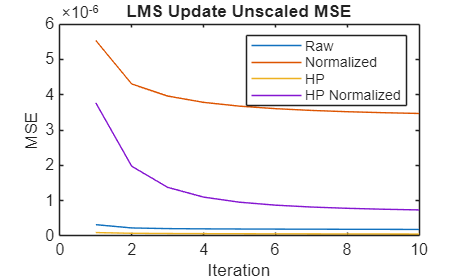

figure
plot(mses)
hold on
plot(mses_norm)
hold on
plot(mses_hp)
hold on
plot(mses_norm_hp)

hold off
title("LMS Update Unscaled MSE")
legend('Raw', 'Normalized', 'HP', 'HP Normalized');
xlabel('Iteration');
ylabel('MSE');

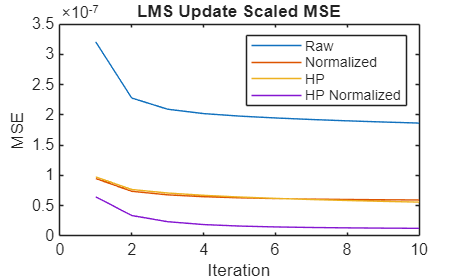

figure
plot(mses)
hold on
plot(mses_norm_scale)
hold on
plot(mses_hp)
hold on
plot(mses_norm_hp_scale)

hold off
title("LMS Update Scaled MSE")
legend('Raw', 'Normalized', 'HP', 'HP Normalized');
xlabel('Iteration');
ylabel('MSE');

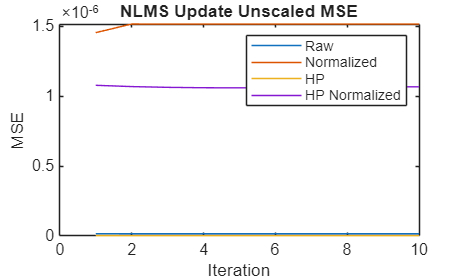

figure
plot(mses_n)
hold on
plot(mses_norm_n)
hold on
plot(mses_n_hp)
hold on
plot(mses_norm_n_hp)

hold off
title("NLMS Update Unscaled MSE")
legend('Raw', 'Normalized', 'HP', 'HP Normalized');
xlabel('Iteration');
ylabel('MSE');

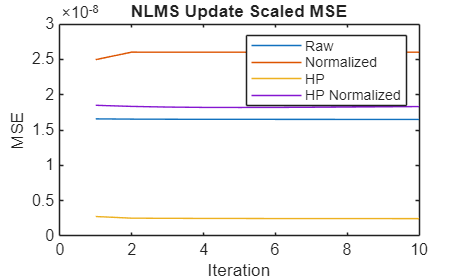

figure
plot(mses_n)
hold on
plot(mses_norm_n_scale)
hold on
plot(mses_n_hp)
hold on
plot(mses_norm_n_hp_scale)

hold off
title("NLMS Update Scaled MSE")
legend('Raw', 'Normalized', 'HP', 'HP Normalized');
xlabel('Iteration');
ylabel('MSE');

step_scale = 1 / (factor^2)

step_scale = 58.3153

norm_nlms = FxLMS(ref_norm, target_norm, panel_ir, filter_order, step_size * 2, true);
[pred_norm_n, mses_norm_n] = norm_nlms.learn(n_iter);

norm_nlms_hp = FxLMS(ref_norm_hp, target_norm_hp, panel_ir_hp, filter_order, step_size * 2, true);
[pred_norm_n_hp, mses_norm_n_hp] = norm_nlms_hp.learn(n_iter);

mses_norm_n_scale = mses_norm_n * factor^2

mses_norm_n_scale = 1.0e-03 *

    0.3069    0.3289    0.3302    0.3297    0.3298    0.3298    0.3297    0.3296    0.3297    0.3298


mses_norm_n_hp_scale = mses_norm_n_hp * factor^2

mses_norm_n_hp_scale = 1.0e-03 *

    0.2587    0.2586    0.2581    0.2582    0.2586    0.2591    0.2597    0.2603    0.2609    0.2614


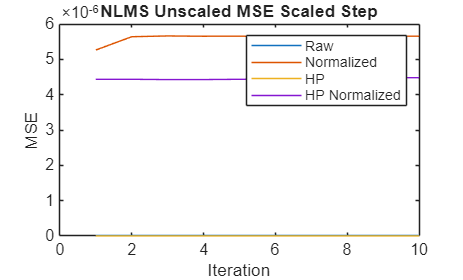

figure
plot(mses_n)
hold on
plot(mses_norm_n)
hold on
plot(mses_n_hp)
hold on
plot(mses_norm_n_hp)

hold off
title("NLMS Unscaled MSE Scaled Step")
legend('Raw', 'Normalized', 'HP', 'HP Normalized');
xlabel('Iteration');
ylabel('MSE');

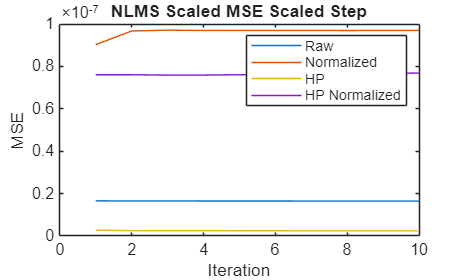

figure
plot(mses_n)
hold on
plot(mses_norm_n_scale)
hold on
plot(mses_n_hp)
hold on
plot(mses_norm_n_hp_scale)

hold off
title("NLMS Scaled MSE Scaled Step")
legend('Raw', 'Normalized', 'HP', 'HP Normalized');
xlabel('Iteration');
ylabel('MSE');